# Spectrum Sensing with Deep Learning to Identify 5G and LTE Signals

This example shows how to train a semantic segmentation network using deep learning for spectrum monitoring. One of the uses of spectrum monitoring is to characterize spectrum occupancy. The neural network in this example is trained to identify 5G NR and LTE signals in a wideband spectrogram. 

## Introduction

Computer vision uses the semantic segmentation technique to identify objects and their locations in an image or a video. In wireless signal processing, the objects of interest are wireless signals, and the locations of the objects are the frequency and time occupied by the signals. In this example we apply the semantic segmentation technique to wireless signals to identify spectral content in a wideband spectrogram. 

In the following, you will:

- Generate training signals. 

-  Apply transfer learning to a semantic segmentation network to identify 5G NR and LTE signals in time and frequency. 

-  Test the trained network with synthetic signals. 

-  Use an SDR to test the network with over the air (OTA) signals.

## Generate Training Data

One advantage of wireless signals in the deep learning domain is the fact that the signals are synthesized. Also, we have highly reliable channel and RF impairment models. As a result, instead of collecting and manually labeling signals, you can generate 5G NR signals using 5G Toolbox™ and LTE signals using LTE Toolbox™ functions. You can pass these signals through standards-specified channel models to create the training data. 

Train the network with frames that contain only 5G NR or LTE signals and then shift these signals in frequency randomly within the band of interest. Each frame is 40 ms long, which is the duration of 40 subframes. The network assumes that the 5G NR or LTE signal occupies the same band for the whole frame duration. To test the network performance, create frames that contain both 5G NR and LTE signals on distinct random bands within the band of interest.

Use a sampling rate of 61.44 MHz. This rate is high enough to process most of the latest standard signals and several low-cost software defined radio (SDR) systems can sample at this rate providing about 50 MHz of useful bandwidth. To monitor a wider band, you can increase the sample rate, regenerate training frames and retrain the network.

Use the [`helperSpecSenseTrainingData`](matlab:openExample('deeplearning_shared/SpectrumSensingWithDeepLearning5GLTEExample','supportingFile','helperSpecSenseTrainingData')) function to generate training frames. This function generates 5G NR signals using the [`helperSpecSenseNRSignal`](matlab:openExample('deeplearning_shared/SpectrumSensingWithDeepLearning5GLTEExample','supportingFile','helperSpecSenseNRSignal')) function and LTE signals using the [`helperSpecSenseLTESignal`](matlab:openExample('deeplearning_shared/SpectrumSensingWithDeepLearning5GLTEExample','supportingFile','helperSpecSenseLTESignal')) function. This table lists 5G NR variable signal parameters.

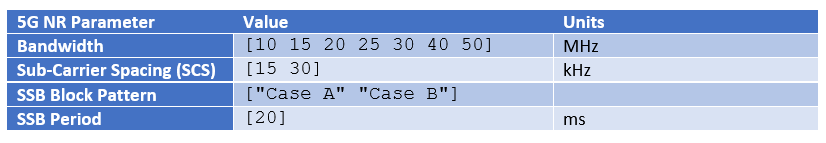

This table lists LTE variable signal parameters.

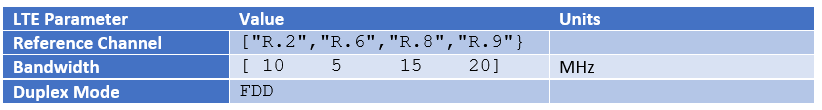

Use the [`nrCDLChannel`](docid:5g_ref#mw_sysobj_nrCDLChannel) and the [`lteFadingChannel`](docid:lte_ref#bt3f52s) functions to add channel impairments. For details of the channel configurations, see the `helperSpecSenseTrainingData` function. This table lists channel parameters. 

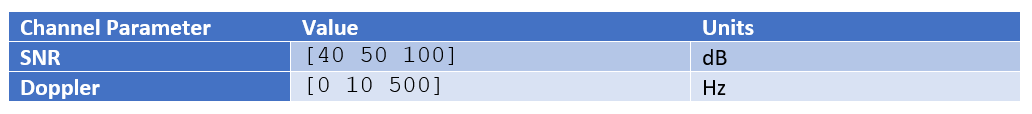

The `helperSpecSenseTrainingData` function uses the [`helperSpecSenseSpectrogramImage`](matlab:openExample('deeplearning_shared/SpectrumSensingWithDeepLearning5GLTEExample','supportingFile','helperSpecSenseSpectrogramImage')) function to create spectrogram images from complex baseband signals. Calculate the spectrograms using an FFT length of 4096. Generate 256 by 256 RGB images. This image size allows a large enough batch of images to fit in memory during training while providing enough resolution in time and frequency. If your GPU does not have sufficient memory, you can resize the images to smaller sizes or reduce the training batch size. 

The `generateTrainData` variable determines whether training data is to be downloaded or generated. Choosing "Use downloaded data" sets the `generateTrainData` variable to `false`. Choosing "Generate training data" sets the `generateTrainData` variable to `true` to generate the training data from scratch. Data generation may take several hours depending on the configuration of your computer. Using a PC with Intel® Xeon® W-2133 CPU @ 3.60GHz and creating a parallel pool with six workers with the Parallel Computing Toolbox™, training data generation takes about an hour. Choose "Train network now" to train the network. This process takes about 20 minutes with the same PC and NVIDIA® Titan V GPU. Choose "Use trained network" to skip network training. Instead, the example downloads the trained network. 

Use 900 frames from each set of signals: 5G NR only, LTE only and 5G NR and LTE both. If you increase the number of possible values for the system parameters, increase the number of training frames. 

imageSize = [256 256];    % pixels
sampleRate = 61.44e6;     % Hz
numSubFrames = 40;        % corresponds to 40 ms
frameDuration = numSubFrames*1e-3;    % seconds
trainDir = fullfile(pwd,'TrainingData');
%tempdir = pwd;

generateTrainData = false;
trainNow = true;

%understand why this algorigthm was chosen
%make signal weaker /lower power and randomise the delaysec in IWNconfig and other bt signals
%make WLAN version of WLAN thing in mornign 
%adjust save pixel image thing
%write down in document whats in the dataset 
if generateTrainData
  numFramesPerStandard = 600;
  helperSpecSenseTrainingData(numFramesPerStandard,imageSize,trainDir,numSubFrames,sampleRate);
end

### Load Training Data

Use the [`imageDatastore`](docid:matlab_ref#butueui-1) function to load training images with the spectrogram of 5G NR and LTE signals. The `imageDatastore` function enables you to efficiently load a large collection of images from disk. Spectrogram images are stored in .png files. 

imds = imageDatastore(trainDir,'IncludeSubfolders',false,'FileExtensions','.png');

Use the [`pixelLabelDatastore`](docid:vision_ref.mw_c2246553-ba4a-4bad-aad4-6ab8fa2f7f2d) function to load spectrogram pixel label image data. Each pixel is labeled as one of "NR", "LTE" or "Noise". A pixel label datastore encapsulates the pixel label data and the label ID to a class name mapping. Pixel labels are stored in .hdf files.

classNames = ["NR" "LTE" "BT" "WLAN" "Noise"];
pixelLabelID = [63 127 191 255 0];
pxdsTruth = pixelLabelDatastore(trainDir,classNames,pixelLabelID,...
  'IncludeSubfolders',false,'FileExtensions','.hdf');

### Analyze Dataset Statistics

To see the distribution of class labels in the training dataset, use the [`countEachLabel`](docid:vision_ref#mw_1c600e69-1a15-4538-9629-7bceaafbd4e7) function to count the number of pixels by class label, and plot the pixel counts by class.

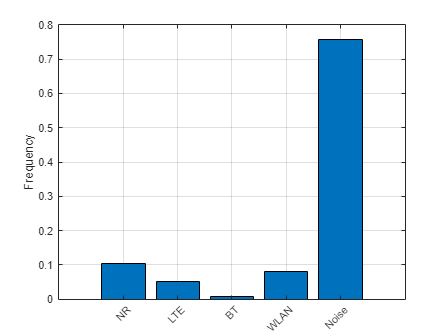

tbl = countEachLabel(pxdsTruth);
frequency = tbl.PixelCount/sum(tbl.PixelCount);
figure
bar(1:numel(classNames),frequency)
grid on
xticks(1:numel(classNames)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

Ideally, all classes would have an equal number of observations. However, with wireless signals it is common for the classes in the training set to be imbalanced. 5G NR signals may have larger bandwidth than LTE signals, and noise fills the background. Because the learning is biased in favor of the dominant classes, imbalance in the number of observations per class can be detrimental to the learning process. In the Balance Classes Using Class Weighting section, class weighting is used to mitigate bias caused by imbalance in the number of observations per class.

### **Prepare Training, Validation, and Test Sets**

The deep neural network uses 80% of the single signal images from the dataset for training and, 20% of the images for validation. The [`helperSpecSensePartitionData`](matlab:openExample('deeplearning_shared/SpectrumSensingWithDeepLearning5GLTEExample','supportingFile','helperSpecSensePartitionData')) function randomly splits the image and pixel label data into training and validation sets.

[imdsTrain,pxdsTrain,imdsVal,pxdsVal] = helperSpecSensePartitionData(imds,pxdsTruth,[80 20]);
cdsTrain = combine(imdsTrain,pxdsTrain);
cdsVal = combine(imdsVal,pxdsVal);

% Apply a transform to resize the image and pixel label data to the desired
% size.
cdsTrain = transform(cdsTrain, @(data)preprocessTrainingData(data,imageSize));
cdsVal = transform(cdsVal, @(data)preprocessTrainingData(data,imageSize));

## Train Deep Neural Network

Use the [`deeplabv3plusLayers`](docid:vision_ref#mw_1db5f1f7-c311-4115-b0df-54380c77c01c) function to create a semantic segmentation neural network. Choose [resnet50](docid:nnet_ref#mw_7e914435-71af-41f7-9ec9-8f2092892982) as the base network and specify the input image size (number of pixels used to represent time and frequency axes) and the number of classes. If the Deep Learning Toolbox™ Model *for ResNet-50 Network* support package is not installed, then the function provides a link to the required support package in the Add-On Explorer. To install the support package, click the link, and then click **Install**. Check that the installation is successful by typing `resnet50` at the command line. If the required support package is installed, then the function returns a [`DAGNetwork`](docid:nnet_ref#mw_219eb8df-d140-434a-ac88-ec6b5f41da47) object.

baseNetwork = 'resnet50';
lgraph = deeplabv3plusLayers(imageSize,numel(classNames),baseNetwork);

### **Balance Classes Using Class Weighting**

To improve training when classes in the training set are not balanced, you can use class weighting to balance the classes. Use the pixel label counts computed earlier with the `countEachLabel` function and calculate the median frequency class weights.

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq;

Specify the class weights using a [`pixelClassificationLayer`](docid:vision_ref#mw_783aebd8-1ff1-4bc6-8508-90c8b71fca32).

pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name,'ClassWeights',classWeights);
lgraph = replaceLayer(lgraph,"classification",pxLayer);

### **Select Training Options**

Configure training using the [`trainingOptions`](docid:nnet_ref#bu59f0q) function to specify the stochastic gradient descent with momentum (SGDM) optimization algorithm and the hyper-parameters used for SGDM. To get the best performance from the network, you can use the [Experiment Manager app](docid:nnet_ref#mw_11ce840f-eed7-4975-9c28-baeebd79f092) to optimize training options. 

opts = trainingOptions("sgdm",...
  MiniBatchSize = 40,...
  MaxEpochs = 20, ...
  LearnRateSchedule = "piecewise",...
  InitialLearnRate = 0.02,...
  LearnRateDropPeriod = 10,...
  LearnRateDropFactor = 0.1,...
  ValidationData = cdsVal,...
  ValidationPatience = 5,...
  Shuffle="every-epoch",...
  OutputNetwork = "best-validation-loss",...
  Plots = 'training-progress')

opts =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.0200
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 20
                   MiniBatchSize: 40
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.TransformedDatastore]
             ValidationFrequency: 50
              ValidationPatience: 5
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoa

Train the network using the combined training data store, `cdsTrain`. The combined training data store contains single signal frames and true pixel labels.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:40 |        9.48% |       70.14% |       2.3226 |       1.3722 |          0.0200 |
|       2 |          50 |       00:18:15 |       94.46% |       93.67% |       0.1504 |       0.1792 |          0.0200 |
|       3 |         100 |       00:35:25 |       95.31% |       94.11% |       0.1222 |       0.1980 |          0.0200 |
|       4 |         150 |       00:53:03 |       96.57% |       95.37% |       0.0767 |   

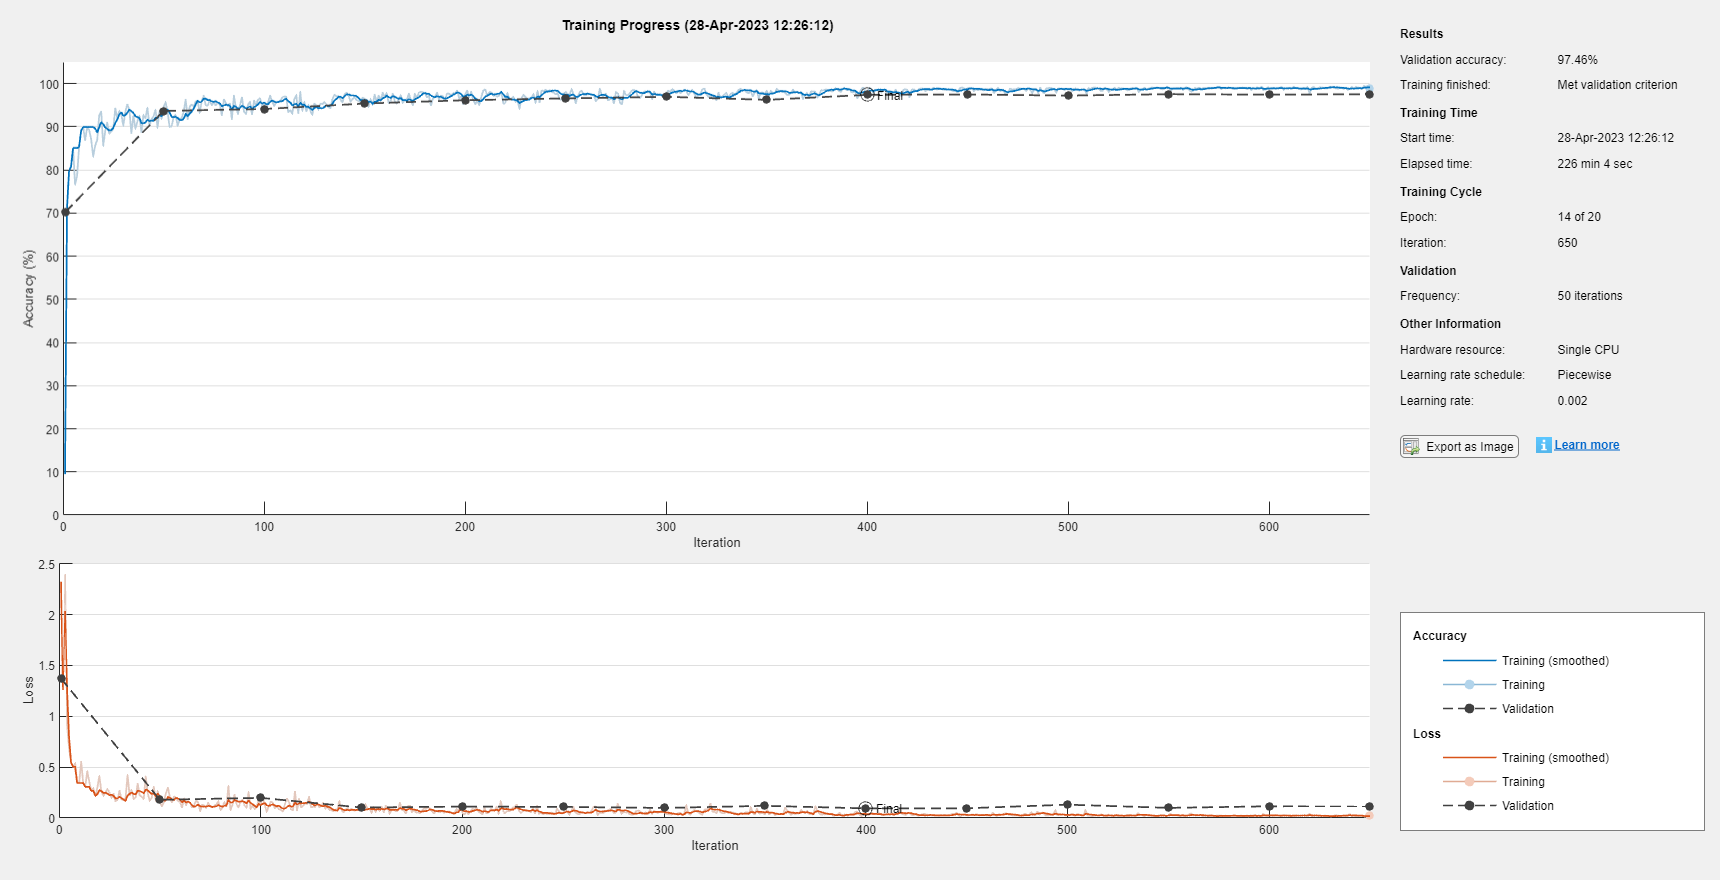

if trainNow
  [net,trainInfo] = trainNetwork(cdsTrain,lgraph,opts); %#ok<UNRCH> 
  save('specSenseTrainedNet','net')
else
  load specSenseTrainedNet net
end

## Test with Synthetic Signals

Test the network signal identification performance using signals that contain both 5G NR and LTE signals. Use the [`semanticseg`](docid:vision_ref#mw_bbecb1af-a6c9-43d1-91f5-48607edc15d1) function to get the pixel estimates of the spectrogram images in the test data set. Use the [`evaluateSemanticSegmentation`](docid:vision_ref#mw_ec14c36c-b93d-4fde-8512-ea7d51651b89) function to compute various metrics to evaluate the quality of the semantic segmentation results. 

dataDir = fullfile(trainDir,'LTE_NR');
dataDir = fullfile(trainDir,'BT_WLAN');
%dataDir = fullfile(trainDir,'BT_MULTI'); doesn't work
dataDir = fullfile(trainDir,'BT_BT');
%dataDir = fullfile(trainDir,'WLAN_MULTI'); doesn't work

imds = imageDatastore(dataDir,'IncludeSubfolders',false,'FileExtensions','.png');
pxdsResults = semanticseg(imds,net,"WriteLocation",tempdir);

Running semantic segmentation network
-------------------------------------
* Processed 599 images.



pxdsTruth = pixelLabelDatastore(dataDir,classNames,pixelLabelID,...
  'IncludeSubfolders',false,'FileExtensions','.hdf');
metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTruth);

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 599 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.51185            NaN         0.10641      0.27731        0.26466  



Plot the normalized confusion matrix for all test frames.

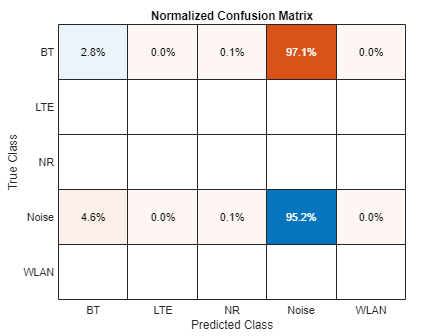

cm = confusionchart(metrics.ConfusionMatrix.Variables, ...
  classNames, Normalization='row-normalized');
cm.Title = 'Normalized Confusion Matrix';

Plot the histogram of the per-image intersection over union (IoU). For each class, IoU is the ratio of correctly classified pixels to the total number of ground truth and predicted pixels in that class.

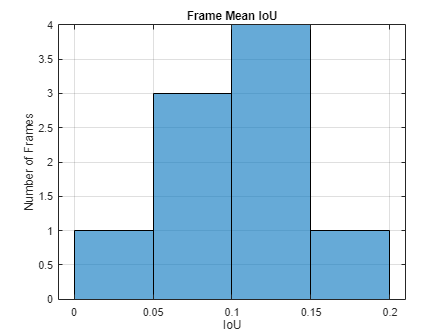

imageIoU = metrics.ImageMetrics.MeanIoU;
figure
histogram(imageIoU)
grid on
xlabel('IoU')
ylabel('Number of Frames')
title('Frame Mean IoU')

Inspecting low SNR frames shows that the spectrogram images do not contain visual features that can help the network identify the low SNR frames correctly. Repeat the same process, considering only the frames with average SNR of 50dB or 100dB and ignoring the frames with average SNR of 40dB. 

files = dir(fullfile(dataDir,'*.mat'));
dataFiles = {};
labelFiles = {};
for p=1:numel(files)
  load(fullfile(files(p).folder,files(p).name),'params');
  if params.SNRdB > 30
    [~,name] = fileparts(files(p).name);
    dataFiles = [dataFiles; fullfile(files(p).folder,[name '.png'])]; %#ok<AGROW>
    labelFiles = [labelFiles; fullfile(files(p).folder,[name '.hdf'])]; %#ok<AGROW>
  end
end
imds = imageDatastore(dataFiles);
pxdsResults = semanticseg(imds,net,"WriteLocation",tempdir);

Running semantic segmentation network
-------------------------------------
* Processed 218 images.



pxdsTruth = pixelLabelDatastore(labelFiles,classNames,pixelLabelID);
metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTruth);

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 218 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.52022            NaN         0.10816      0.28578        0.2676   



Considering only the set of frames with higher SNR, replot the normalized confusion matrix and observe the improved network accuracy.

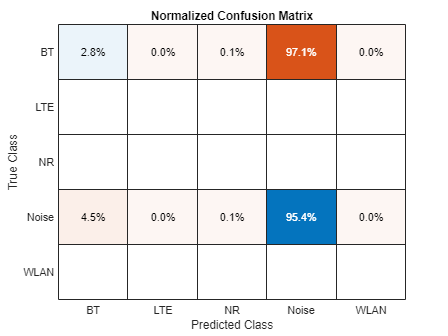

cm = confusionchart(metrics.ConfusionMatrix.Variables, ...
  classNames, Normalization='row-normalized');
cm.Title = 'Normalized Confusion Matrix';

Considering only the set of frames with higher SNR, replot the per-image IoU histogram and observe the improved distribution.

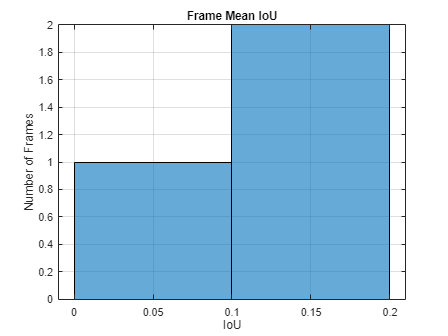

imageIoU = metrics.ImageMetrics.MeanIoU;
figure
histogram(imageIoU)
grid on
xlabel('IoU')
ylabel('Number of Frames')
title('Frame Mean IoU')

### Identify 5G NR and LTE Signals in Spectrogram

Visualize the received spectrum, true labels, and predicted labels for the image with index 602.

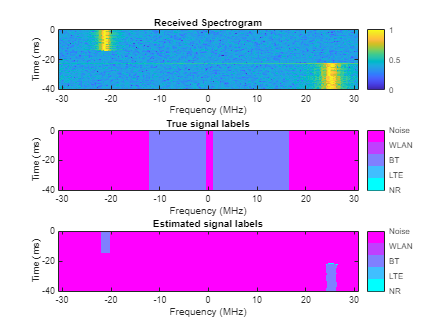

imgIdx = 32;
rcvdSpectrogram = readimage(imds,imgIdx);
trueLabels = readimage(pxdsTruth,imgIdx);
predictedLabels = readimage(pxdsResults,imgIdx);
figure
helperSpecSenseDisplayResults(rcvdSpectrogram,trueLabels,predictedLabels, ...
  classNames,sampleRate,0,frameDuration)

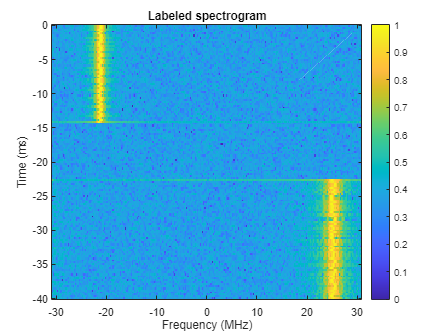

figure
helperSpecSenseDisplayIdentifiedSignals(rcvdSpectrogram,predictedLabels, ...
  classNames,sampleRate,0,frameDuration)

## SECTION I DIDNT USE - Test with Over-the-Air Signals

Test the performance of the trained network using over-the-air signal captures. Find a nearby base station and tune the center frequency of your radio to cover the band of the signals you want to identify. This example sets the center frequency to 2.35 GHz. If you have at least one ADALM-PLUTO radio and have installed [Communication Toolbox Support Package for ADALM-PLUTO Radio](https://www.mathworks.com/hardware-support/adalm-pluto-radio.html), you can run this section of the code. In case you do not have access to an ADALM-PLUTO radio, this example shows results of a test conducted using captured signals. 

runSDRSection = false;
if helperIsPlutoSDRInstalled()  
  radios = findPlutoRadio();
  if length(radios) >= 1
    runSDRSection = true;
  else
    disp("At least one ADALM-PLUTO radios is needed. Skipping SDR test.")
  end
else
    disp("Communications Toolbox Support Package for Analog Devices ADALM-PLUTO Radio not found.")
    disp("Click Add-Ons in the Home tab of the MATLAB toolstrip to install the support package.")
    disp("Skipping SDR test.")
end

Communications Toolbox Support Package for Analog Devices ADALM-PLUTO Radio not found.


Click Add-Ons in the Home tab of the MATLAB toolstrip to install the support package.


Skipping SDR test.


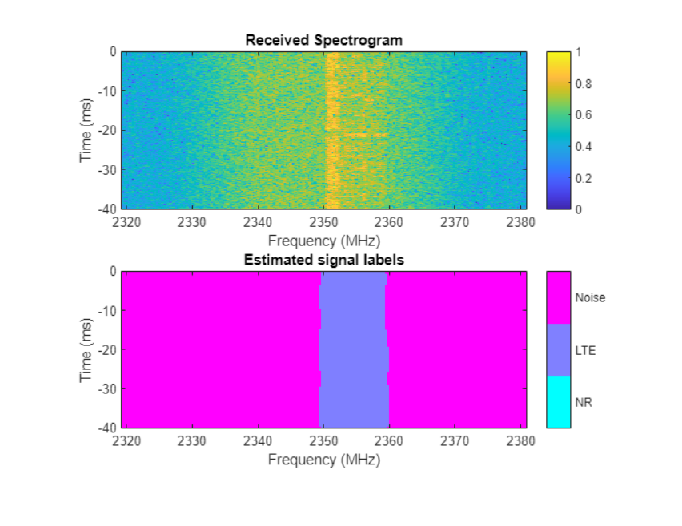

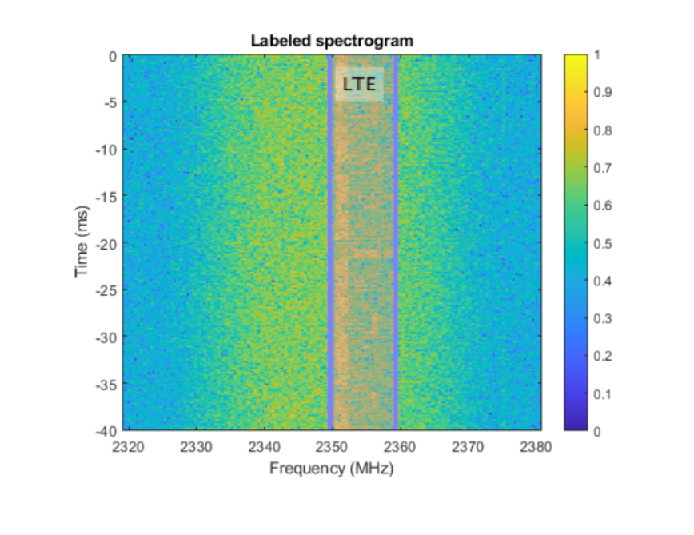

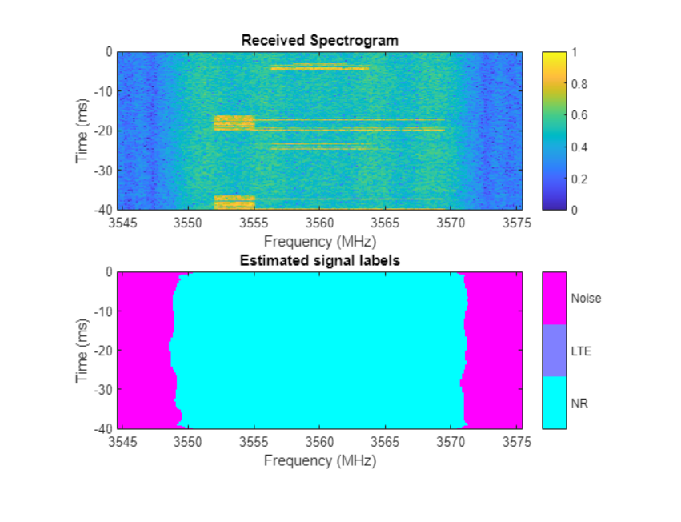

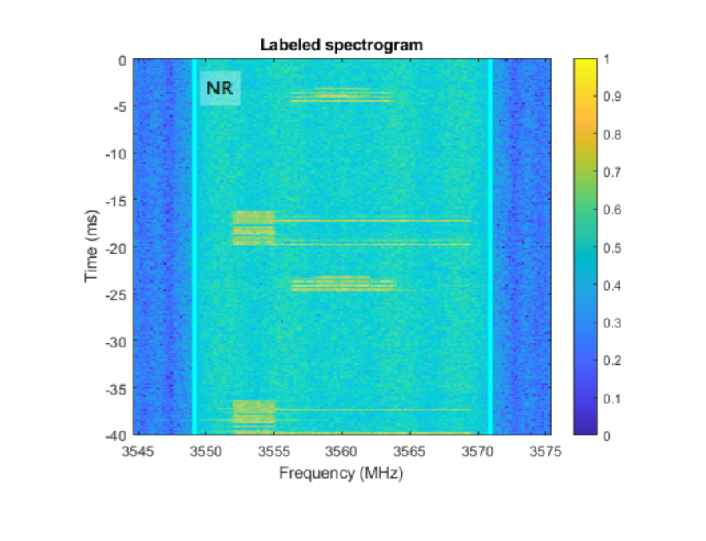

if runSDRSection
  % Set up PlutoSDR receiver
  rx = sdrrx('Pluto');
  rx.CenterFrequency = 2.35e9;
  rx.BasebandSampleRate = sampleRate;
  rx.SamplesPerFrame = frameDuration*rx.BasebandSampleRate;
  rx.OutputDataType = 'single';
  rx.EnableBurstMode = true;
  rx.NumFramesInBurst = 1;
  Nfft = 4096;
  overlap = 10;

  meanAllScores = zeros([imageSize numel(classNames)]);
  segResults = zeros([imageSize 10]);
  for frameCnt=1:10
    rxWave = rx();
    rxSpectrogram = helperSpecSenseSpectrogramImage(rxWave,Nfft,sampleRate,imageSize);

    [segResults(:,:,frameCnt),scores,allScores] = semanticseg(rxSpectrogram,net);
    meanAllScores = (meanAllScores*(frameCnt-1) + allScores) / frameCnt;
  end
  release(rx)

  [~,predictedLabels] = max(meanAllScores,[],3);
  figure
  helperSpecSenseDisplayResults(rxSpectrogram,[],predictedLabels,classNames,...
    sampleRate,rx.CenterFrequency,frameDuration)
  figure
  freqBand = helperSpecSenseDisplayIdentifiedSignals(rxSpectrogram,predictedLabels,...
    classNames,sampleRate,rx.CenterFrequency,frameDuration)
else
  figure
  imshow('lte_capture_result1.png')
  figure
  imshow('lte_capture_result2.png')
  figure
  imshow('nr_capture_result1.png')
  figure
  imshow('nr_capture_result2.png')
end

## Conclusions and Further Exploration

The trained network can distinguish 5G NR and LTE signals including two example captures from real base stations. The network may not be able to identify every captured signal correctly. In such cases, enhance the training data either by generating more representative synthetic signals or capturing over-the-air signals and including these in the training set. 

You can use the LTE [Cell Search, MIB and SIB1 Recovery](docid:lte_ug#example-SIB1RecoveryExample) and the [NR Cell Search and MIB and SIB1 Recovery](docid:5g_ug#mw_a4db8282-8f25-4802-8b02-548bab69b7dd) examples to identify LTE and 5G NR base stations manually to capture training data, respectively. 

If you need to monitor wider bands of spectrum, increase the `sampleRate`, regenerate the training data and retrain the network.

## Supporting Functions

function data = preprocessTrainingData(data, imageSize)
% Resize the training image and associated pixel label image.
data{1} = imresize(data{1},imageSize);
data{2} = imresize(data{2},imageSize);
end

*Copyright 2021-2022 The MathWorks, Inc.*